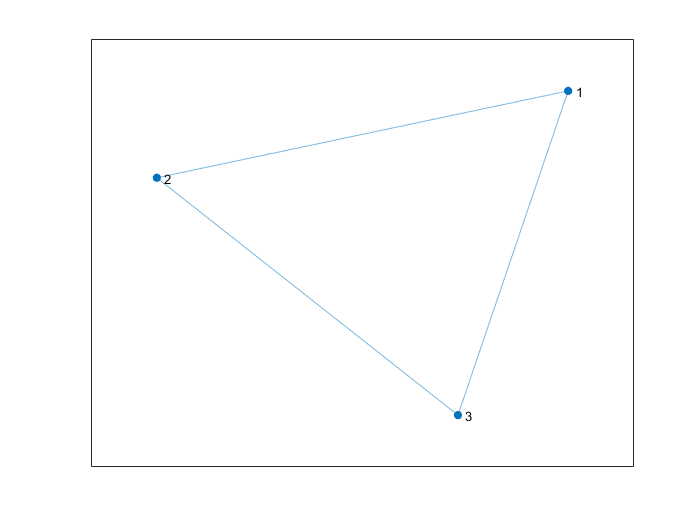

A = [0 1 1;
     1 0 1;
     1 1 0];
plot(graph(A))

## Fiedler Vector and Resistance Curver

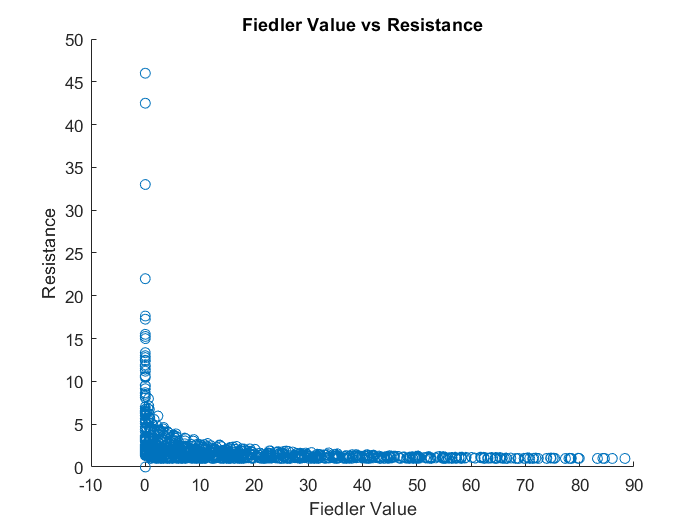

trials = 1000;
n = 5;
F = zeros(trials, 1);
R = zeros(trials, 1);
for t=1:trials
    % Make graph
    A = generate_random_network('ER', randi([2, 100]), rand);
    % Compute Laplacian = D - A
    L = diag(sum(A)) - A;
    eigenvalues = eig(L);
    % Compute fiedler value
    fiedler = eigenvalues(2);
    % Compute Resistance
    idxs = find(abs(eigenvalues) > 0.0001);
    first_nonzero = min(idxs);
    eigenvalues = eigenvalues(first_nonzero:end);
    resistance = length(A) * sum(1/eigenvalues);
    % Save
    F(t) = fiedler;
    R(t) = resistance;
end

% Make plot
scatter(F, R);
title('Fiedler Value vs Resistance');
xlabel('Fiedler Value'); ylabel('Resistance');